# **FARCI Example 1**

In Example 1, we analyze “small1” dataset provided in the [First Neural Connectomics Challenge](http://connectomics.chalearn.org/) that contains calcium imaging data for 100 neurons and their positions in 2D. (data availble in the examples subfolder of FARCI).

From FARCI folder, we run the `Main.m `script file. The "subfunctions" folder along with all the subfolders are added to the path.

% This script takes calcium imaging data as input and returns the underlying neuronal connectome

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
warning ('off','all'); clear; clc; close all; 
path = genpath('subfunctions'); addpath(path); clear path;

## 1. INPUTS

First, the user will be asked to enter deconvolution parameters, in particular, imaging rate and fluorescence decay rate.

INPUTS.ops = sp_deconv_inputs(); % Taking imaging rate and fluorescence decay rate as inputs

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## 2. DATA

Run the following section and import Samll-1 dataset (available in the subfolder examples/small1).

INPUTS.calcium = import_data(); % NN by NT (NN: number of neurons, NT: number of time frames)

****Please upload calcium imaging data. Accepted file formats: .mat .csv .xlsx .txt **** 
Done
Processing...


`****Please upload calcium imaging data. Accepted file formats: .mat .csv .xlsx .txt **** `

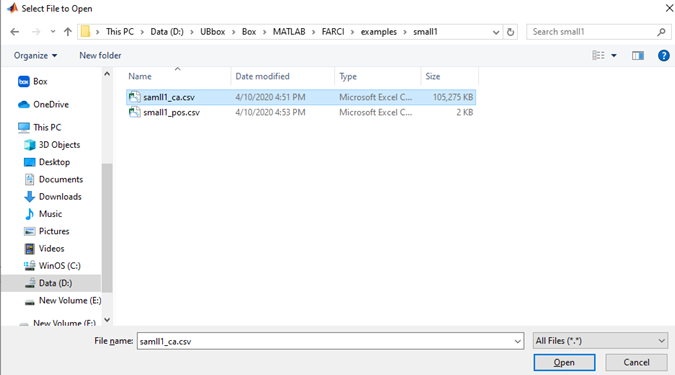

`Done`

`Processing...`

## 3. Spike Deconvolution

Once the data is imported, the deconvolution algorithm, i.e. Suite2P and OASIS, will run and spike data will be generated.

RESULTS.spikes = sp_deconv(INPUTS.ops,INPUTS.calcium); % Non-negative deconvolution using Suite2P and OASIS packages

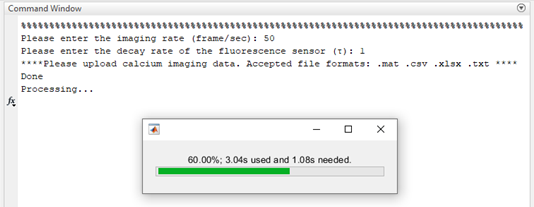

## 4. Spike Denoising

The first preprocessing step is removing the noise from the inferred spikes using the below equation:


$$\Theta_i= \mu_i+2\sigma_i$$


Where $\Theta_i
$ is the threshold for spikes of neuron i, $\mu_i
$ and $\sigma _i
$ are mean and standard deviation of the spikes, respectively.

RESULTS.spikes = sp_denoise(RESULTS.spikes); % Removing the noise present in deconvolved spikes using an optimal threshold

## 5. Spike Smoothing

The second step of preprocessing is the smoothing of denoised spikes using the below smoothing function:


$$h{\left(y_i^t \right)}=\frac{1}{3}y_i^{t-2} +\frac{2}{3}y_i^{t-1} +y_i^t +\frac{2}{3}y_i^{t+1} +\frac{1}{3}y_i^{t+2}$$


Where $y_i^t$ denotes the denoised spike for neuron i at time t.

RESULTS.spikes = sp_smooth(RESULTS.spikes); % Smoothing the spikes to improve the accuracy of connectome inference

## 6. Partial Correlation

After obtaining and processing the spikes, the partial correlation coefficients are calculated using the matrix inversion method.

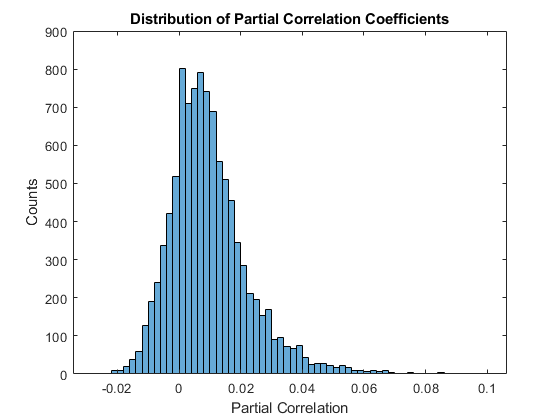

RESULTS.partial_correlation = partial_corr(RESULTS.spikes); % Computing partial correlation using matrix inversion

Once the partial correlation coefficients are computed, the distribution of partial correltaions will be displayes.

## 7. Connectome Inference

According to the distribution of partial correlations, user decides what level of thresholding is appropriate to remove the noise from the network. Here, the thresholding is defined as $Threshold=\mu +\alpha \times \sigma$, where   and   are the mean and standard deviation of partial correlations, respectively. The parameter $\alpha
$ is a cut-off parameter – the higher the value, the sparser is the inferred connectome. we recommend using a value between 1 to 3. Here, we use a conservative threshold $\alpha=3$.

Once, $\alpha$ is specified a heatmap of the neuronal connectome will be displayed.

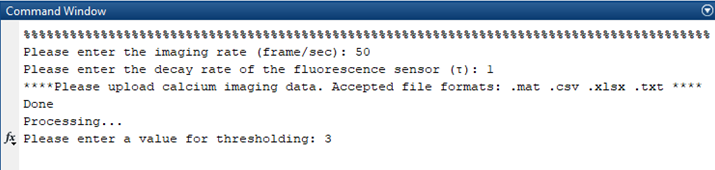

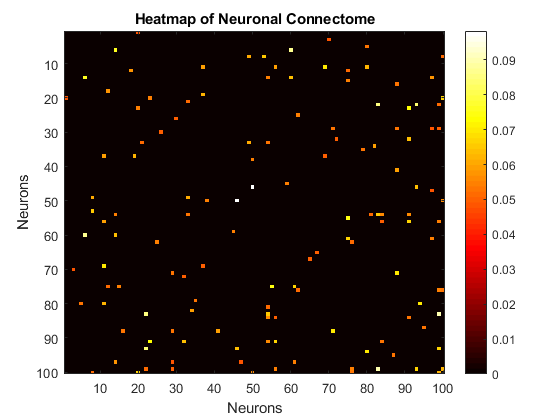

[RESULTS.network,RESULTS.edges] = connectome_inf(RESULTS.partial_correlation); % Connectome Inference based on partial correlation coeff.

## 8. Circular Graph

In this section, a circular network will be generated.

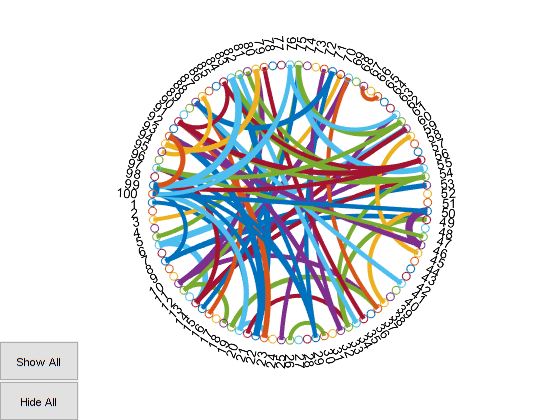

circular_graph = circ_graph(RESULTS.network); % Circular graph of the inferred neuronal connectome

## 9. Graph with positions

When spatial information is available, connectome can be visualize with actual position of neurons. A pop-up question will appear; If entered 1, the user will be asked to upload the position data either in form of an $\left(n\times n\right)$ pairwise distance matrix, where *n* is number of neurons, or an ${\left(n\times 2\right)}$ matrix with the x-y coordinates of the neurons. In this example, the x and y coordinates for each neuron is given.

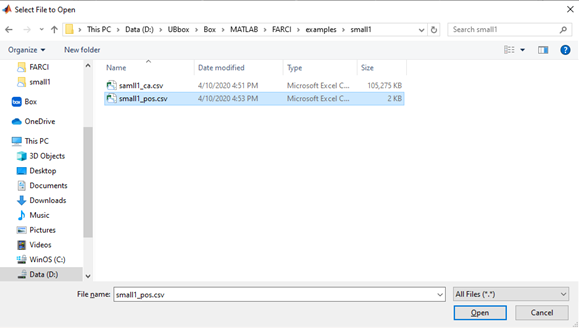

Would you like to visualize the connectome with actual positions?


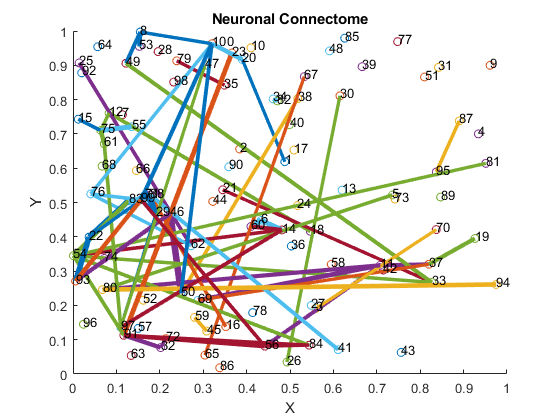

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% THE END %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


pos_graph = graph_w_positions(RESULTS.network); % inferred neuronal connectome based on actual spatial arrangement of neurons